# Image segmentation to measure colony growth

First, we're going to open a colony image using `imread` and then display it with `imshow`. We need to tell MATLAB where to navigate for the image files.

image=imread('colony_growth_25.tif')

image = 367×405 uint8 matrix
   43   48   45   46   51   40   43   43   46   49   51   47   49   40   42   45   52   44   45   42   48   47   40   42   40   47   45   42   46   45   43   45   41   42   43   42   46   52   45   46   49   43   43   46   46   48   44   42   41   39
   44   44   42   46   50   53   52   47   49   50   49   43   49   44   44   45   45   47   47   42   46   47   49   48   47   50   52   43   44   49   47   45   51   51   41   37   46   40   46   40   42   42   47   43   44   50   47   46   47   47
   43   39   45   46   47   49   51   47   45   52   41   46   49   49   46   43   42   51   47   47   42   47   44   51   49   44   35   44   40   49   52   46   55   44   43   49   42   49   49   51   47   46   51   43   43   44   43   53   48   43
   51   42   49   42   42   45   46   48   43   43   41   43   49   51   40   48   47   50   49   38   46   45   42   44   51   46   49   45   47   47   44   46   48   46   45   48   51   42   39   45   47   44   50   

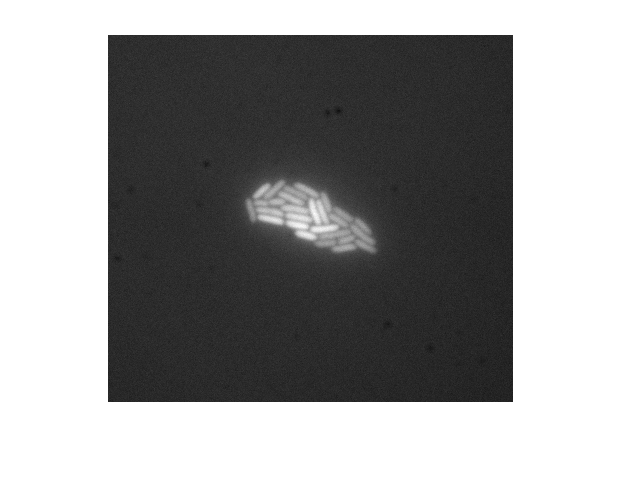

imshow(image);

Use `imtool` to inspect pixel values and determine a threshold for segmentation.

%imtool(image);     %commented this out so that it doesn't constantly run

We're drawing a threshold so we can teach the computer what's a cell and what isn't. What does it mean to draw a threshold? We'll use an example of a vector given by 

a=[2,3,1,6,4,3];

Let's draw a threshold of 3 over this vector to demonstrate what thresholds do.

a<3

ans = 1×6 logical array
   1   0   1   0   0   0


The idea is we want to figure out what part of the image is cells, and what is background. The easiest way to do that is to set the color at a certain threshold. Any pixel values brighter/whiter than this threshold in our black and white images are part of a cell. We can use the area of the cell to calculate how many cells the bright white pixels represent.

Now we're going to threshold our colony image and check how we did.

threshold=100;
ImThresh=image>threshold;

Now display the thresholded image:

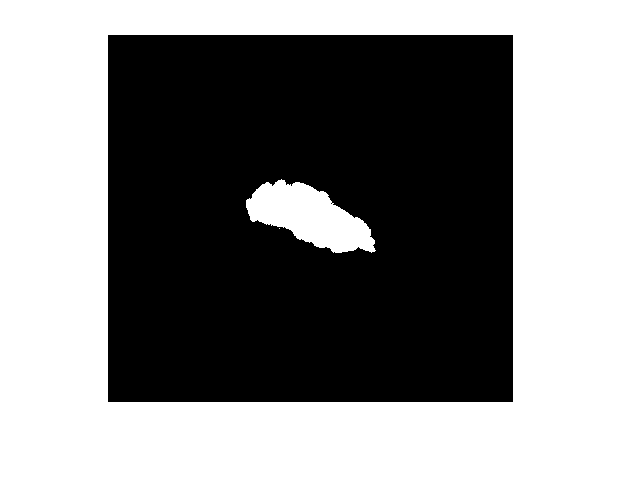

imshow(ImThresh);

Now we can find the total area of the colony by summing the values (1s) in the image matrix. We will use the sum command, which sums all of the elements of a vector. For example, let's look again at vector a.

a

a =      2     3     1     6     4     3


sum(a)

ans = 19

Let's look at an example matrix

b=[1,2,3;4,5,6;7,8,9]

b =      1     2     3
     4     5     6
     7     8     9


sum(b)

ans =     12    15    18


This sums up every column in the matrix and returns it as a new value. If we apply sum() one more time, we'll get the sum of all the numbers in the matrix.

sum(sum(b))

ans = 45

Now let's do this with our thresholded image

sum(sum(ImThresh))

ans = 5408

## Calculating the colony size for all images

Now we know how to find the area for one image. We can do this automatically for all of the images using a for loop.

First, make a list of all the image names to run through. We can do this using the command `dir`.

FileList=dir('ColonyGrowthData/*.tif');

Let's look at our list. A structure array (the "struct array") is a datatype that can store multiple kinds of data at once (like strings and booleans, etc).

FileList

FileList = 37×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Let's examine the information corresponding to file number 12. Note that the images themselves started with image 00.

FileList(12)

ans = struct with fields:
       name: 'colony_growth_11.tif'
     folder: '/Users/Me/Documents/MATLAB/ColonyGrowthData'
       date: '15-Jun-2016 08:59:40'
      bytes: 148783
      isdir: 0
    datenum: 7.3650e+05


If you want to get a specific field such as the file name, you have to do the following:

FileList(12).name

ans = 'colony_growth_11.tif'

If we want to load the image, we might need to add more than just the file name (such as the folder it's contained in). As a result, we need to concatenate a string corresponding to the folder, etc. Strings concatenate as follows:

a='Hel'

a = 'Hel'

b='lo'

b = 'lo'

[a,b]

ans = 'Hello'

Using spaces works pretty similarly.

a='Hello';
b=' ';
c='world!';
[a,b,c]

ans = 'Hello world!'

Now we're ready to analyze the images. First, let's pre-allocate an array in which to store all of the areas as we calculate them.

Area=zeros(1, length(FileList)); %makes a vector filled with zeroes that's 1 by length(FileList)

We will build a time vector as we fill in our area vector

TimeInterval=5; %interval btw image acquisitions (in minutes)
TimeVect=[]; %Pre-allocating an array

Now we want to loop through all of the images doing the following:

1.) Open the image

2.) Threshold the image

3.) Sum the area of the bacteria & store the info in Area

4.) Add to TimeVect

for i=1:length(FileList)
    image=imread(FileList(i).name);
    ImThresh=image>threshold;
    Area(i)=sum(sum(ImThresh));
    TimeVect(i)=(i-1)*TimeInterval;
end

## Plotting colony growth

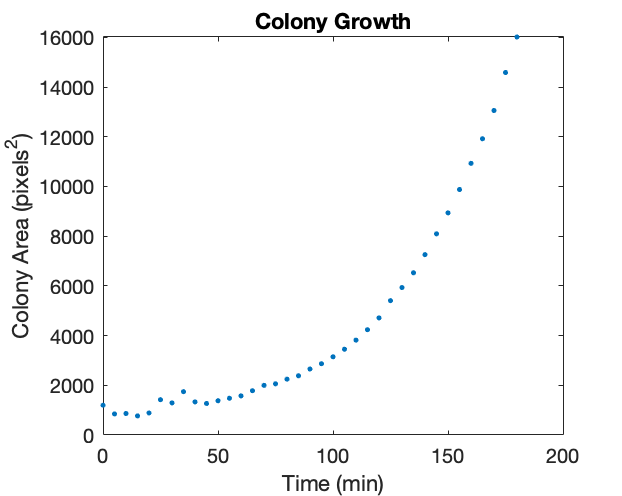

plot(TimeVect, Area,'.');     % '.' causes the data to be plotted as points
xlabel('Time (min)');
ylabel('Colony Area (pixels^2)');
title('Colony Growth');

Now let's plot the data on a log scale on the y-axis using the semilogy() function.

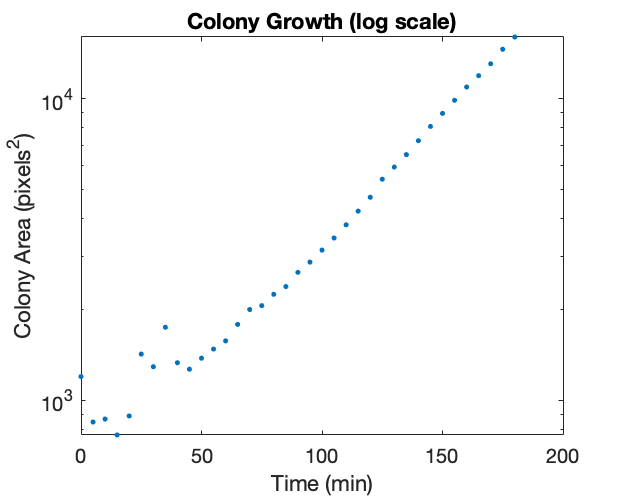

semilogy(TimeVect,Area,'.');
xlabel('Time (min)');
ylabel('Colony Area (pixels^2)');
title('Colony Growth (log scale)');